data=load("sonar_data.csv"); 

data_20cm = data(1:150);
data_40cm = data(250:400);
data_60cm = data(470:640);
data_80cm = data(810:870);
data_100cm = data(1025:1150);
data_120cm = data(1250:end-80);

all_data = [data_20cm;data_40cm;data_60cm;data_80cm;data_100cm;data_120cm];
mean_all_data=[mean(data_20cm);mean(data_40cm);mean(data_60cm);mean(data_80cm);mean(data_100cm);mean(data_120cm)];
std_all_data=[std(data_20cm);std(data_40cm);std(data_60cm);std(data_80cm);std(data_100cm);std(data_120cm)];
expected = [20;40;60;80;100;120];

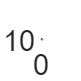


plot(expected/100,(expected-mean_all_data)*10)
grid 
xlabel('Afstand til væggen [m]')
ylabel('Gennemsnitlig afvigelse [mm] ')

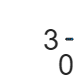

plot(expected/100,std_all_data*10)
xlabel('Afstand til væggen [m]')
ylabel('Standard afvigelse [mm]')
grid